Antena Transmissora

ant1 = spiralArchimedean('Turns',4,'Tilt',90,'TiltAxis','Y')

ant1 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 4
         InnerRadius: 5.0000e-04
         OuterRadius: 3.9800e-02
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


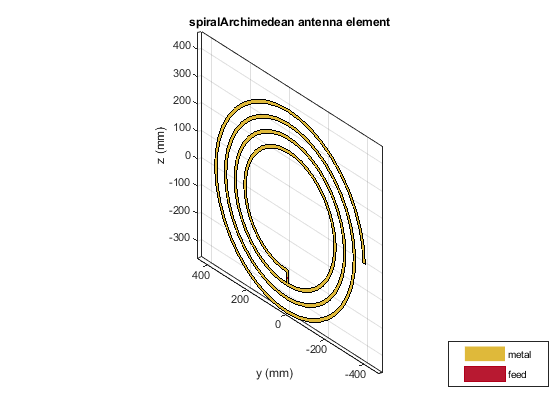

ant1.NumArms = 1;
ant1.OuterRadius = 40e-2;
ant1.InnerRadius = 20e-2;
show(ant1)

Impedância da antena

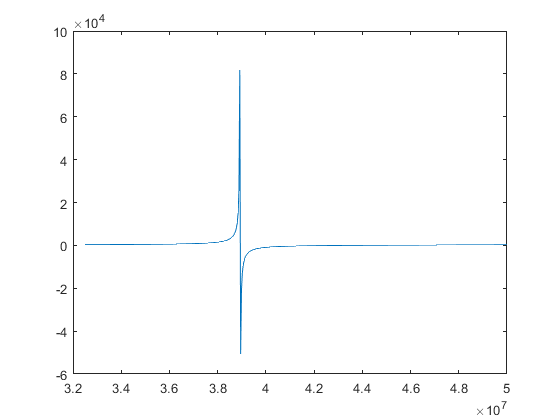

f = linspace(3.25e7,5e7,500);

impedancia = impedance(ant1,f);

imaginario = imag(impedancia);

figure 
plot(f,imaginario)

Antena Receptora

ant2 = spiralArchimedean('Turns',4,'Tilt',90,'TiltAxis','Y')

ant2 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 4
         InnerRadius: 5.0000e-04
         OuterRadius: 3.9800e-02
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


ant2.NumArms = 1;
ant2.Tilt = 90;
ant2.OuterRadius = 40e-2;
ant2.InnerRadius = 20e-2;
show(ant2)

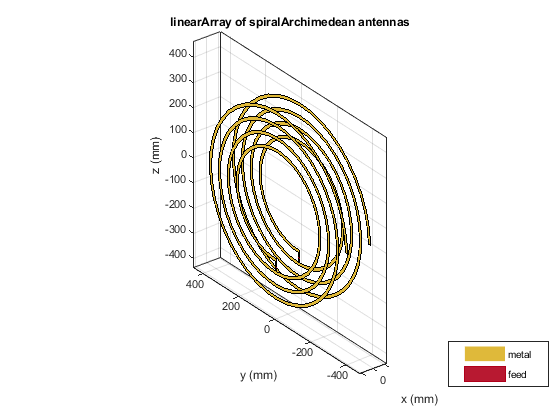

array = linearArray('Element',[ant1,ant2],'ElementSpacing',0.1);
show(array)

Simulando

ganhos = sparameters(array,f)

ganhos =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [500×1 double]
     Parameters: [2×2×500 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


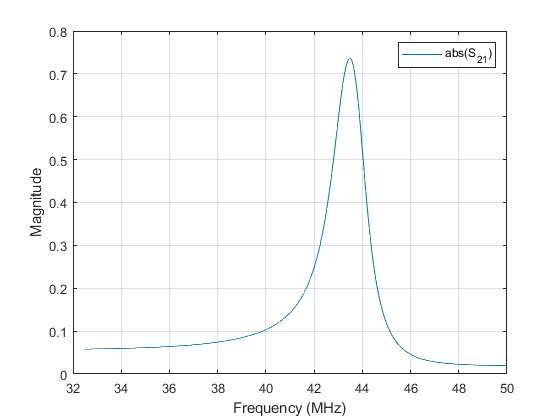


rfplot(ganhos,2,1,'abs')

values = rfparam(ganhos,2,1);
ganho_maximo = abs(max(values))

ganho_maximo =    7.3634e-01


i_max = find(abs(values) == ganho_maximo)

i_max =    314


f(i_max)

ans =    4.3477e+07


Em 3D

g = zeros(30,500);

d = linspace(0.1, 0.6, 30);

for n = 1:1:30
    
    array = linearArray('Element',[ant1,ant2],'ElementSpacing',d(1,n));
    sp = sparameters(array,f);
    g(n,:) = abs(rfparam(sp,2,1));
    
end

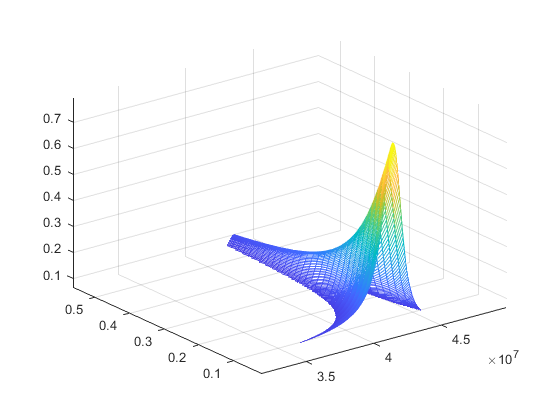

mesh(f,d,g)

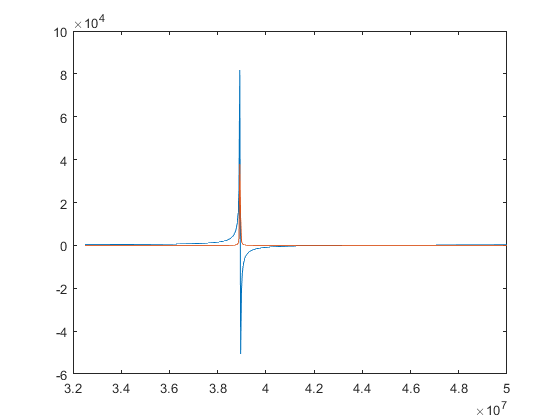

plot(f,imag(impedancia),f,real(impedancia));

format shortE

freq1 = 43.5471e6;
freq2 = 43.6172e6;
w1 = 2*pi*freq1;
w2 = 2*pi*freq2;

z1 = -1.18038;
z2 = 3.80925;

% w1*L - 1/(w1*C) = z1
% w2*L - 1/(w2*C) = z2
A = [w1 -1/w1;w2 -1/w2];
B = [z1;z2];

X = linsolve(A,B);


L = X(1)

L =    5.6666e-06


C = 1/(X(2))

C =    2.3554e-12


wr = 1/sqrt(L*C)

wr =    2.7372e+08


freq_r = wr/(2*pi)

freq_r =    4.3564e+07



%frequencia de ressonancia com precisão de 4 casas decimais

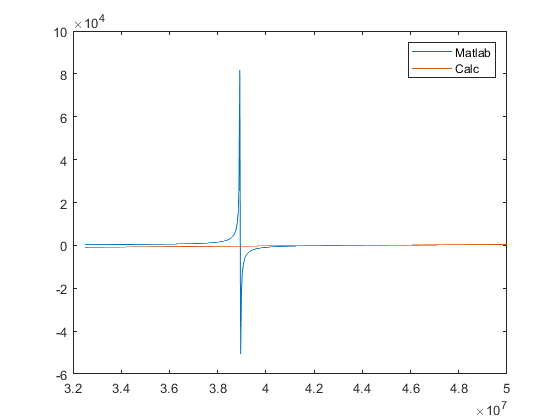

w = f*2*pi;
Imp = w.*(L*1j) + 1./(w.*(C*1j));

plot(f,imag(impedancia),f,imag(Imp))
legend('Matlab','Calc')

R = real(impedance(ant1,freq_r));
U = 1;

%I1 = U./(R-((wr.*M.*1j.*wr.*M.*1j)./R));
%I2 = abs((wr.*M.*1j.*I1)./R);

%P2 = I2.^2*R;
%P1 = I1*U;

%G = zeros(1,6);

%for n = [1,2,3,4,5,6]
%    ganho = (abs(P2(1,n))/abs(P1(1,n)));
%    G(1,n) = ganho;
%end

gzinho = zeros(1,30);
for n = 1:1:30
    
    array = linearArray('Element',[ant1,ant2],'ElementSpacing',d(1,n));
    sp = sparameters(array,freq_r);
    gzinho(1,n) = abs(rfparam(sp,2,1));
    
end

k = zeros(1,30);
for n = 1:1:30
    kzinho = sqrt((gzinho(1,n)*R^2)/((-gzinho(1,n) + 1)*wr^2))*(1/L);
    k(1,n) = kzinho;
end

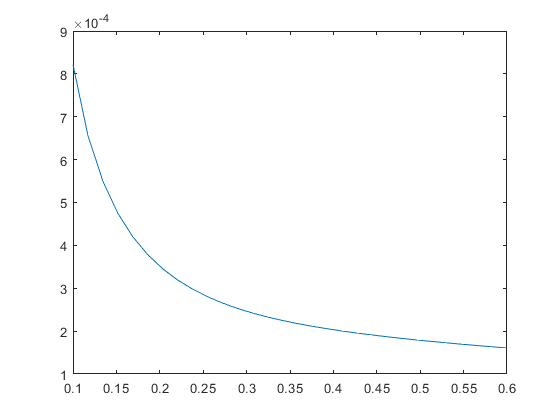

plot(d,k)

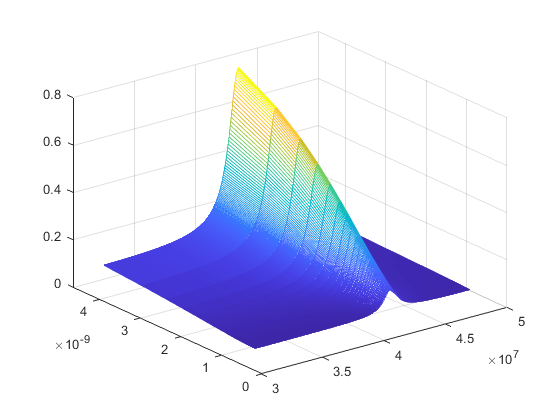

M = k*L;
mesh(f,M,g)

% G = (jwM)^2/(R1*Rc + (jwM)^2)
% M^2 = G*R1*Rc/(w^2-G^2*w^2)